# ECM307-G01T02L03D - Atividade T3

%% Atividade T3 - Análise de Vogais
%% Luis Guilherme de Souza Munhoz RA: 20.01937-8 Lab: 3


## Instruções

%%%% primeiro descomente a sessão de leitura
%%%% em seguida comente a sessão de análise
%%%% agora rode o código
%%%% depois comente a sessão de leitura e descomente a sessão de análise e
%%%% rode o código novamente

## Boas Práticas

clc;                                       % limpa a tela
clear all;                                 % limpar as variáveis
close all;                                 % fecha as figuras abertas

## Leitura das vogais e armazenamento em arquivo Vogais.mat

% % prealocando
% a = cell(1,5);
% a{1,5} = [];
% 
% % prealocando
% e = cell(1,5);
% e{1,5} = [];
% 
% % prealocando
% i = cell(1,5);
% i{1,5} = [];
% 
% % prealocando
% o = cell(1,5);
% o{1,5} = [];
% 
% % prealocando
% u = cell(1,5);
% u{1,5} = [];
% 
% for ii = 1:5
% %%%% Leitura da vogal a
%     File = "a" + ii + ".wav";
%     
%     [Y,FS] = audioread(File);
%     
%     a{:,ii} = Y;
%     
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%% Leitura da vogal e
%     File = "e" + ii + ".wav";
% 
%     [Y,FS] = audioread(File);
%     
% 
%     e{:,ii} = Y;
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%% Leitura da vogal i
%     File = "i" + ii + ".wav";
% 
%     [Y,FS] = audioread(File);
% 
%     i{:,ii} = Y;
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%% Leitura da vogal o
%     File = "o" + ii + ".wav";
% 
%     [Y,FS] = audioread(File);
% 
%     o{:,ii} = Y;
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%% Leitura da vogal u
%     File = "u" + ii + ".wav";
%     
%     [Y,FS] = audioread(File);
% 
%     u{:,ii} = Y;
% 
% end
% save('Vogais.mat', 'a', 'e', 'i', 'o', 'u');

## Carregando o arquivo das vogais e as analisando

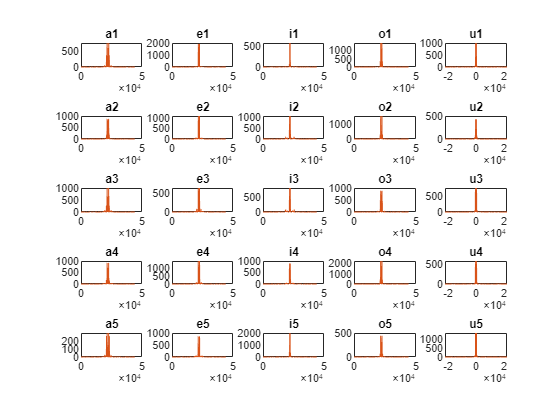

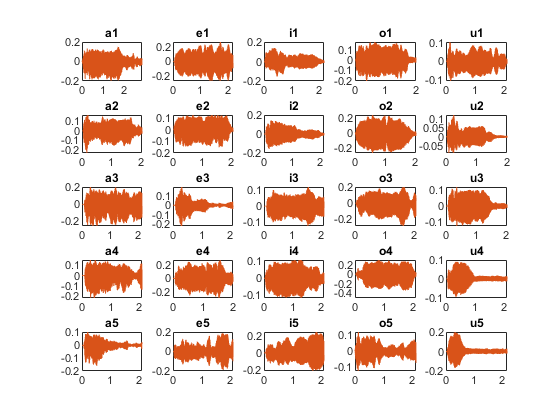

k = 0;
jj = 0;
% preallocation
a = cell(1,5);

% preallocation
e = cell(1,5);

% preallocation
i = cell(1,5);

% preallocation
o = cell(1,5);

% preallocation
u = cell(1,5);

load('Vogais.mat')
FS = 44100;
for ii = 1:5
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% analise da vogal a    
    %%%%% reduzindo o tamanho de a
    N       = length(a{:,ii});               
    Ts      = 1/FS;                     
    ws      = 2*pi*FS;                
    duracao = N*Ts;                    
    tempo   = linspace(0,duracao,N);   
    fmax    = FS/2;
    k = k + 1;

    %%%% espectro de amplitude


    figure(1)
    freq = linspace(0,FS,N);
    subplot(5,5,k);
    plot(freq,fftshift(abs(fft(a{:,ii}))));
    title("a" + ii);

    
    %%%% plotando a série temporal
    

    figure(2)
    N       = length(a{:,ii});
    duracao = N*Ts; 
    tempo   = linspace(0,duracao,N);
    subplot(5,5,k);
    plot(tempo, a{:,ii});
    title("a" + ii);
    
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% analise da vogal e    
    %%%%% reduzindo o tamanho de e
    
    N       = length(e{:,ii});               
    Ts      = 1/FS;                     
    ws      = 2*pi*FS;                
    duracao = N*Ts;                    
    tempo   = linspace(0,duracao,N);   
    fmax    = FS/2;
    k = k + 1;

    %%%% espectro de amplitude


    figure(1)
    freq = linspace(0,FS,N);
    subplot(5,5,k);
    plot(freq,fftshift(abs(fft(e{:,ii}))));
    title("e" + ii);

    
    %%%% plotando a série temporal
    

    figure(2)
    N       = length(e{:,ii});
    duracao = N*Ts; 
    tempo   = linspace(0,duracao,N);
    subplot(5,5,k);
    plot(tempo, e{:,ii});
    title("e" + ii);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% analise da vogal i    
    %%%%% reduzindo o tamanho de i
    N       = length(i{:,ii});               
    Ts      = 1/FS;                     
    ws      = 2*pi*FS;                
    duracao = N*Ts;                    
    tempo   = linspace(0,duracao,N);   
    fmax    = FS/2;
    k = k + 1;

    %%%% espectro de amplitude


    figure(1)
    freq = linspace(0,FS,N);
    subplot(5,5,k);
    plot(freq,fftshift(abs(fft(i{:,ii}))));
    title("i" + ii);

    
    %%%% plotando a série temporal
    

    figure(2)
    N       = length(i{:,ii});
    duracao = N*Ts; 
    tempo   = linspace(0,duracao,N);
    subplot(5,5,k);
    plot(tempo, i{:,ii});
    title("i" + ii);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% analise da vogal o    
    %%%%% reduzindo o tamanho de o
    N       = length(o{:,ii});               
    Ts      = 1/FS;                     
    ws      = 2*pi*FS;                
    duracao = N*Ts;                    
    tempo   = linspace(0,duracao,N);   
    fmax    = FS/2;
    k = k + 1;

    %%%% espectro de amplitude


    figure(1)
    freq = linspace(0,FS,N);
    subplot(5,5,k);
    plot(freq,fftshift(abs(fft(o{:,ii}))));
    title("o" + ii);

    
    %%%% plotando a série temporal
    

    figure(2)
    N       = length(o{:,ii});
    duracao = N*Ts; 
    tempo   = linspace(0,duracao,N);
    subplot(5,5,k);
    plot(tempo, o{:,ii});
    title("o" + ii);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% analise da vogal u   
    %%%%% reduzindo o tamanho de u
    N       = length(u{:,ii});               
    Ts      = 1/FS;                     
    ws      = 2*pi*FS;                
    duracao = N*Ts;                    
    tempo   = linspace(0,duracao,N);   
    fmax    = FS/2;
    k = k + 1;

   %%%% espectro de amplitude


    figure(1)
    freq = linspace(-FS/2,FS/2,N);
    subplot(5,5,k);
    plot(freq,fftshift(abs(fft(u{:,ii}))));
    title("u" + ii);

    
    %%%% plotando a série temporal
    

    figure(2)
    N       = length(u{:,ii});
    duracao = N*Ts; 
    tempo   = linspace(0,duracao,N);
    subplot(5,5,k);
    plot(tempo, u{:,ii});
    title("u" + ii);
end

## análise da primeira vogal a

figure(3);
t0 = 0.934225;
N       = length(a{:,1});
duracao = N*Ts; 
picosA1 = a{:,1}(41200:41499);
tempo   = linspace(0,duracao,N)-t0;
tempoa1 = linspace(tempo(41200), tempo(41499), length(picosA1))

tempoa1 =     0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011


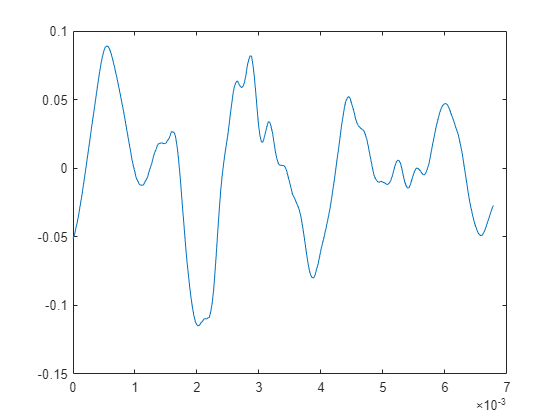


plot(tempoa1,picosA1)

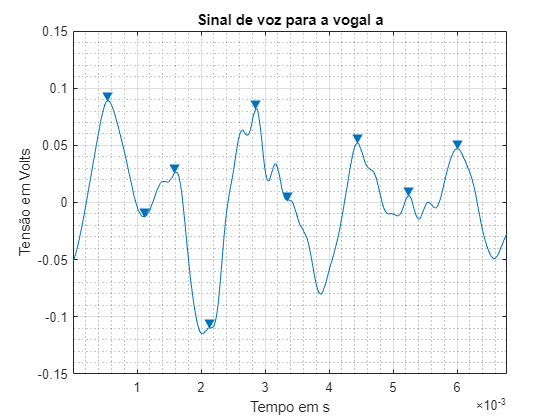

%%% Analisando os parâmteros graficamente

ti = 0.000544349;  % começo do primeiro período inteiro
tf = 0.00600925;   % fim do último período inteiro

T = (tf-ti)/13; % valor médio dentre os 13 períodos
f = inv(T);     % frequência associada a vibração gerada

findpeaks(picosA1,tempoa1,'MinPeakDistance',T);

[vt,tp]=findpeaks(picosA1,tempoa1,'MinPeakDistance',T);

Tm =mean(diff(tp));

title('Sinal de voz para a vogal a');
xlabel('Tempo em s');
ylabel('Tensão em Volts'); 
grid minor

figure(4)
freq = linspace(-FS/2,FS/2,N);
freq = freq(N/2+1:N);
Y0 = fft(a{:,1});
Y0 = Y0(N/2+1:N);

Y0 = 	1.0e+02 *

  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 - 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0000 + 0.0000i  -0.0001 - 0.0000i  -0.0001 + 0.0000i  -0.0001 - 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0001i  -0.0001 + 0.0000i  -0.0001 - 0.0000i  -0.0001 + 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 + 0.0000i  -0.0001 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0001 + 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0000 + 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0000 + 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 + 0.0000i  -0.0001 - 0.0000i


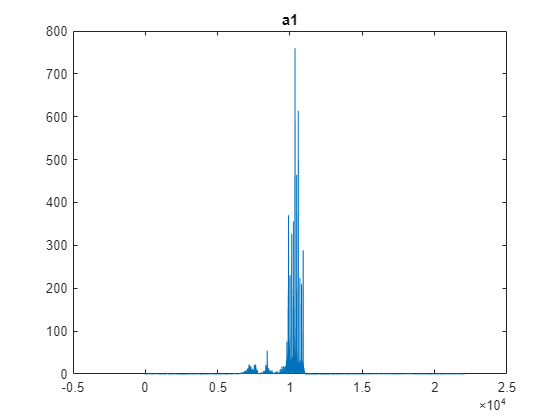


plot(freq,fftshift(abs(Y0)));
title("a"+ 1);